## **Load Data**

warning('off')
addpath('C:\Users\hsuen\Desktop\NBAnet\data');
statsForNBA = readtable('nba odds 2019-20.xlsx');
warning('off')
statsForNBA = [statsForNBA; readtable('nba odds 2018-19.xlsx')];
statsForNBA = [statsForNBA; readtable('nba odds 2017-18.xlsx')];
statsForNBA = [statsForNBA; readtable('nba odds 2016-17.xlsx')];
statsForNBA = [statsForNBA; readtable('nba odds 2015-16.xlsx')];
statsForNBA = [statsForNBA; readtable('nba odds 2014-15.xlsx')];
statsForNBA = [statsForNBA; readtable('nba odds 2013-14.xlsx')];

## **Pre-Process Data and Add New Features**

trainData = table;

statsForNBA.VH = categorical(statsForNBA.VH);
statsForNBA.Team = categorical(statsForNBA.Team);

awayTeamData = statsForNBA(statsForNBA.VH == 'V', :);
homeTeamData = statsForNBA(statsForNBA.VH == 'H', :);

awayTeamData = awayTeamData(:, [4 5 9 12]);
homeTeamData = homeTeamData(:,[4 5 9 12] );

awayTeamData.Properties.VariableNames = {'AwayTeam', 'AwayFirstQuarter', 'AwayFinal', 'AwayML'};
homeTeamData.Properties.VariableNames = {'HomeTeam', 'HomeFirstQuarter', 'HomeFinal', 'HomeML'};

trainData = horzcat(awayTeamData, homeTeamData);

homeOverAway = trainData.HomeFirstQuarter./trainData.AwayFirstQuarter;
homeMinusAway = trainData.HomeFirstQuarter - trainData.AwayFirstQuarter;

homeTeamWin = trainData.HomeFinal > trainData.AwayFinal;

trainData = addvars(trainData, homeOverAway, homeMinusAway , homeTeamWin,'NewVariableNames', {'HomeOverAway', 'HomeMinusAway','HomeTeamWin'});

**Going off of just Vegas odds, how well do they do at prediciting the home team winning? Ultimately we want to do better. Vegas odds roughly at 0.6866. We will see that our classifiers do better by looking at RAPM stats for the year and first quarter match ups.**

## **Input Your Test Data**

load myModel.mat

testBet = trainData;

testBet{1,'AwayTeam'} = categorical({'Cleveland'});
testBet{1, 'AwayFirstQuarter'} = 26;
testBet{1,'AwayML'} = -100;
testBet{1,'HomeTeam'} = categorical({'Detroit'});
testBet{1,'HomeFirstQuarter'} = 32;
testBet{1,'HomeML'} = -100;
testBet{1,'HomeOverAway'} = 0.9;
testBet{1,'HomeMinusAway'} = -3;

testBet = testBet(1,:);

homeTeamWins = trainedModel.predictFcn(testBet)

homeTeamWins = logical
   0


## **Train On Different Data Set**

load('nbaData2.mat')

% scale data set
games.AST_away = rescale(games.AST_away);
games.AST_home = rescale(games.AST_home);

games.REB_away = rescale(games.REB_away);
games.REB_home = rescale(games.REB_home);

% % generate new features 
% games.REB_compare_quotient = games.REB_away./games.REB_home;
% games.AST_compare_quotient = games.AST_away./games.AST_home;
% 
% games.REB_compare_difference = games.REB_away - games.REB_home;
% games.AST_compare_difference = games.AST_away - games.AST_home;
% 
% % create "indicator" variables
% games.FG_great_home = categorical(games.FG_PCT_home > games.FT_PCT_home);
% games.FG_great_away = categorical(games.FG_PCT_away > games.FT_PCT_away);
% 
% games.FG3_great_home = categorical(games.FG3_PCT_home > (1.2 .*games.FG3_PCT_away));
% games.FG3_great_away = categorical(games.FG3_PCT_away > (1.2 .*games.FG3_PCT_home));

## **Create an SVM Predictor**

numObservations = height(games);
kernScale = sqrt(numObservations);
percentToHold = 0.3;
myModel = fitcsvm(games,"HOME_TEAM_WINS", "KernelFunction","gaussian","Standardize",true,...
    "CategoricalPredictors",{'HOME_TEAM_ID', 'VISITOR_TEAM_ID', },...
    'KernelScale', kernScale, 'BoxConstraint', 1 , 'Holdout',percentToHold);

## **Evaluate Performance**

testInds = test(myModel.Partition);   % Extract the test indices
XTest = games(testInds,:);
YTest = games(testInds,:);

% to run the predictions, none of the variables can be categorical (the SVM
% already knows which ones to do so)

XTest.HOME_TEAM_ID = double(XTest.HOME_TEAM_ID);
XTest.VISITOR_TEAM_ID = double(XTest.VISITOR_TEAM_ID);
yfit = predict(myModel.Trained{1}, XTest);  

numCorrect = yfit == YTest.HOME_TEAM_WINS;
acc = sum(numCorrect) / numObservations / percentToHold

acc = 0.7741

## **Predict on New Data Points**


testBet = games(1,:);

homeTeam = 'Pelicans';
awayTeam = 'Jazz';

homeTeam = ismember(teams.NICKNAME, homeTeam);
awayTeam = ismember(teams.NICKNAME, awayTeam);

testBet{1,'HOME_TEAM_ID'} = teams{homeTeam,1};
testBet{1, 'VISITOR_TEAM_ID'} = teams{awayTeam, 1};
testBet{1,'FG_PCT_home'} = 0.465;
testBet{1,'FT_PCT_home'} = 0.769;
testBet{1,'FG3_PCT_home'} = 0.50;
testBet{1,'AST_home'} = 11;
testBet{1,'REB_home'} = 23;
testBet{1,'FG_PCT_away'} = 0.457;
testBet{1,'FT_PCT_away'} = 0.60;
testBet{1,'FG3_PCT_away'} = 0.308;
testBet{1,'AST_away'} = 12;
testBet{1,'REB_away'} = 22;

% testBet.REB_compare_quotient = testBet.REB_away./testBet.REB_home;
% testBet.AST_compare_quotient = testBet.AST_away./games.AST_home;
% 
% testBet.REB_compare_difference = testBet.REB_away - testBet.REB_home;
% testBet.AST_compare_difference = testBet.AST_away - testBet.AST_home;
% 
% % create "indicator" variables
% testBet.FG_great_home = categorical(testBet.FG_PCT_home > testBet.FT_PCT_home);
% testBet.FG_great_away = categorical(testBet.FG_PCT_away > testBet.FT_PCT_away);
% 
% testBet.FG3_great_home = categorical(testBet.FG3_PCT_home > (1.2 .*testBet.FG3_PCT_away));
% testBet.FG3_great_away = categorical(testBet.FG3_PCT_away > (1.2 .*testBet.FG3_PCT_home));

testBet.HOME_TEAM_ID = double(testBet.HOME_TEAM_ID);
testBet.VISITOR_TEAM_ID = double(testBet.VISITOR_TEAM_ID);

homeTeamWins = predict(myModel.Trained{1},testBet)

homeTeamWins = 1

## **Predictor Importance Estimates**

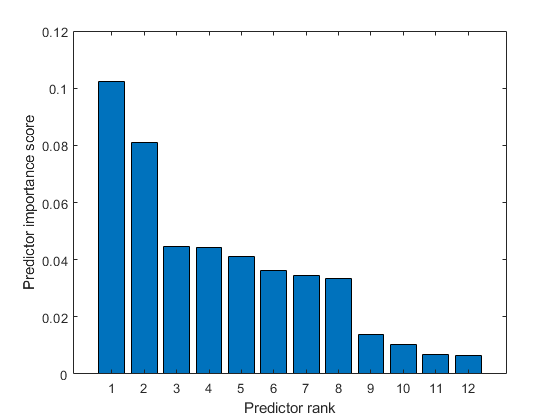

[importantPreds, scores] = fscmrmr(games,"HOME_TEAM_WINS");

bar(scores(importantPreds))
xlabel('Predictor rank')
ylabel('Predictor importance score')

% based on these results, only the first 8 predictors are important

## **Retrain With Only Top 8 Predictors**


myModel = fitcsvm(games(:, importantPreds(1:8)), games.HOME_TEAM_WINS, "KernelFunction","gaussian","Standardize",true,...
    'KernelScale', kernScale, 'BoxConstraint', 1 , 'Holdout',percentToHold);

## **Add the "Plus-Minus" Statistic Of Players (train a better model?)**

load nbaData3.mat

% create a new feature, a teams PlusMinus Score
% need to create a different PlusMinus Score for each team for each year
% looping through number of teams and also number of years

numTeams = length(teams.TEAM_ID);
yearsOfGames = 2003:2020;
numYears = length(yearsOfGames);

games.GAME_ID = categorical(games.GAME_ID);
gamesdetails.GAME_ID = categorical(gamesdetails.GAME_ID);
mergingTable = games(:,{'GAME_ID', 'GAME_DATE'});

gamesdetails = innerjoin(mergingTable, gamesdetails);

% create the master matrix for prediction
plusMinusMatrix = cell(numTeams,numYears);

for i = 1:numTeams
    for j = 1:numYears
        yearInQuestion = yearsOfGames(j);
        relevantGames = gamesdetails(gamesdetails.GAME_DATE == yearInQuestion,:);
        gamesForTeam = relevantGames(ismember(relevantGames.TEAM_ID, teams.TEAM_ID(i)),:);
        
        plusMinusTeam = gamesForTeam.PLUS_MINUS;
        plusMinusTeam(isnan(plusMinusTeam)) = [];
        teamPlusMinus = sum(plusMinusTeam) / length(plusMinusTeam);
        plusMinusMatrix{i,j} = teamPlusMinus;
    end
   
end

% now need to loop through the games table and then add the relevant
% PlusMinus Statistic into the table. Will not really be able to use this
% for new data points but can determine if accuracy goes up 

numGames = height(games);

awayPlusMinus = zeros(numGames,1);
homePlusMinus = zeros(numGames,1);

for i = 1:numGames
    homeTeam = ismember(teams.TEAM_ID, games.HOME_TEAM_ID(i));
    awayTeam = ismember(teams.TEAM_ID, games.VISITOR_TEAM_ID(i));
    year = ismember(yearsOfGames,games.GAME_DATE(i));
    
    awayPlusMinus(i) = plusMinusMatrix{awayTeam,year};
    homePlusMinus(i) = plusMinusMatrix{homeTeam,year};
end
games.HomePlusMinus = homePlusMinus;
games.AwayPlusMinus = awayPlusMinus;

**Now can train a bunch of different models, SVM performed well, and the accuracy went up from 82% to 85%. So an increase of 3% accuracy, thats not bad. How does vegas do with its odds?**